# Modulschlussprüfung  Juli  2010 

# Allgemeine Elektrotechnik 2 (aet2) 

%******************************************************************************
% \details     : 
% \autor       : Simon Burkhardt
% \file        : 
% \date        : 21.06.2018
% \version     : 1.0
%******************************************************************************
clear all; clc
format shorteng

## Aufgabe 1

U41_ = 200*cis(90, 'deg');
U12_ = 200*cis(0, 'deg');
U23_ = 400*cis(-90, 'deg');
I1_ = -10;
I2_ = 15*cis(-45, 'deg');
I3_ = 20*cis(135, 'deg');

% a)
U34_ = 0-U41_-U12_-U23_;
ppcomp(U34_, 'U34_', 'V')

ans = "U34_ = 282.8427 V cis( 135° )"

I4_ = -(I1_+I2_+I3_);
ppcomp(I4_, 'I4_', 'A')

ans = "I4_ = 13.9897 A cis( -14.6388° )"


% c)
Stot_ = (U12_+U23_+U34_)*I1_' + (U23_+U34_)*I2_' + (U34_)*I3_'

Stot_ =      5.6569e+003 -  2.2426e+003i



% d)
P1 = real( (U12_+U23_+U34_)*I1_' )

P1 =      0.0000e+000


P2 = real( (U23_+U34_)*I2_' )

P2 =      0.0000e+000


P3 = real( (U34_)*I3_' )

P3 =      5.6569e+003


P = P1+P2+P3

P =      5.6569e+003


## Aufgabe 2

clear
Rl = 600;
Rq = 100;
Pl = 49e-3;
f1 = 25e6; T1 = 1/f1; w1 = 2*pi*f1;
f2 = 50e6; T2 = 1/f2; w2 = 2*pi*f2;

% a)
Ul = sqrt(Pl*Rl);
Il = Ul/Rl;
Uq = Il * (Rl+Rq)

Uq =      6.3259e+000


Pav = Uq^2/(4*Rq)

Pav =    100.0417e-003



% b) Rq < Rl
% Lösung 1
X3 = j*sqrt(Rq*(Rl-Rq))

X3 =      0.0000e+000 +223.6068e+000i


X4 = -j/(sqrt( 1/Rl*(1/Rq-1/Rl) ))

X4 =      0.0000e+000 -268.3282e+000i


C4 = 1/(j*w1*X4)

C4 =     23.7254e-012


L3 = X3/(j*w1)

L3 =      1.4235e-006


% Lösung 2
X3 = -X3

X3 =      0.0000e+000 -223.6068e+000i


X4 = -X4

X4 =      0.0000e+000 +268.3282e+000i


C3 = 1/(j*w1*X3)

C3 =     28.4705e-012


L4 = X4/(j*w1)

L4 =      1.7082e-006


% Kontrolle
Rll = par(1/(j*w1*C4), Rq+j*w1*L3)

Rll =    600.0000e+000


Rqq = j*w1*L3 + par(Rl, 1/(j*w1*C4))

Rqq =    100.0000e+000 + 28.4217e-015i


Rll = par(j*w1*L4, Rq+1/(j*w1*C3))

Rll =    600.0000e+000 +312.2502e-015i


Rqq = 1/(j*w1*C3) + par(Rl, j*w1*L4)

Rqq =    100.0000e+000 - 56.8434e-015i



% c)
Z_ = Rq + j*w2*L3 + par(Rl, 1/(j*w2*C4));
I_ = Uq/( Z_ );
S_ = Uq*I_'

S_ =     43.3916e-003 +107.8072e-003i


Pq = abs(I_)^2*real(Rq)

Pq =     33.7490e-003


Pl = real(S_) - Pq

Pl =      9.6426e-003


## Aufgabe 3

clear; close
Up = 400;
w1 = 2e4; f1 = w1/(2*pi); T1 = 1/f1;
L = 100e-3;
C = 100e-9;
R1 = 100;
R2 = 1000;

% a)
U_ = Up/sqrt(2) * cis(0, 'deg');
Z_ = 1/(j*w1*C) + R1 + par(R2, j*w1*L);
I_ = U_ / Z_;
S_ = U_*I_'

S_ =     87.8049e+000 -  9.7561e+000i



% b)
U = abs(U_);
I = abs(I_);
t=linspace(0, 1.5*T1, 1e3);
ut = Up * cos(w1*t);
it = abs(I_)*sqrt(2)*cos(w1*t+angle(I_));
pt1 = abs(U_)*abs(I_)* (cos(2*w1*t + angle(U_) + angle(I_)) + cos(angle(U_)-angle(I_)))

pt1 =    175.6098e+000   175.4101e+000   175.1792e+000   174.9172e+000   174.6242e+000   174.3002e+000   173.9455e+000   173.5602e+000   173.1443e+000   172.6980e+000   172.2215e+000   171.7149e+000   171.1785e+000   170.6124e+000   170.0168e+000   169.3919e+000   168.7380e+000   168.0553e+000   167.3440e+000   166.6044e+000   165.8367e+000   165.0413e+000   164.2183e+000   163.3682e+000   162.4911e+000   161.5875e+000   160.6576e+000   159.7018e+000   158.7203e+000   157.7137e+000   156.6821e+000   155.6260e+000   154.5458e+000   153.4418e+000   152.3144e+000   151.1641e+000   149.9912e+000   148.7962e+000   147.5795e+000   146.3415e+000   145.0826e+000   143.8034e+000   142.5042e+000   141.1855e+000   139.8479e+000   138.4917e+000   137.1175e+000   135.7257e+000   134.3169e+000   132.8914e+000


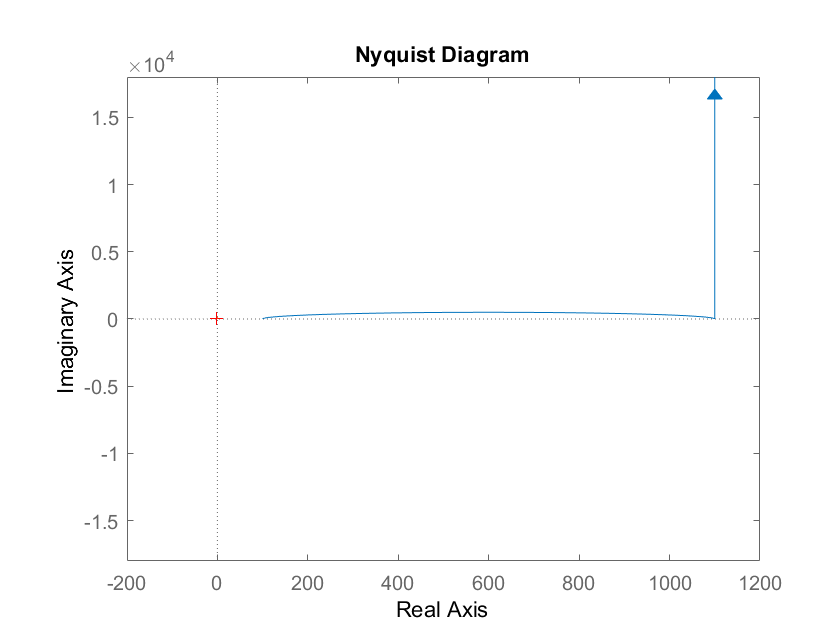

pt2 = ut.*it;
plot(t, pt1); grid on; hold on
plot(t, pt2);

% c)
% w2 = Inf;
s = tf('s');
H = s*C + R1 + 1/( 1/R2 + 1/(s*L));
ny=nyquistplot(H);
setoptions(ny,'ShowFullContour','off')

## Aufgabe 4

clear; close
L = 100e-9;
C = 100e-12;
R = 100;
tau = R*C;
% b)
w = 0;
Z0_ = j*w*L + par(R, 1/(j*w*C))

Z0_ =    100.0000e+000


Z0_ = j*w*L - (j*tau)/(C*(w*tau-j));
w = 20e6*(2*pi);
Z20_ = j*w*L + par(R, 1/(j*w*C))

Z20_ =     38.7727e+000 - 36.1568e+000i


Z20_ = j*w*L - (j*tau)/(C*(w*tau-j));
w = 75e6*(2*pi);
Z75_ = j*w*L + par(R, 1/(j*w*C))

Z75_ =      4.3091e+000 + 26.8177e+000i


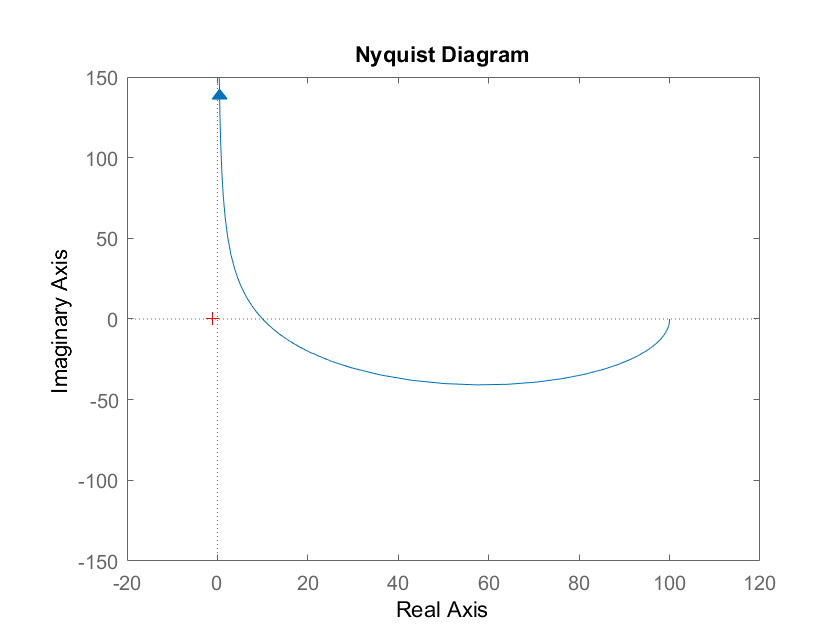

Z75_ = j*w*L - (j*tau)/(C*(w*tau-j));

% c)
s = tf('s');
HZ = s*L + 1/( 1/R + (s*C) );
ny=nyquistplot(HZ);
setoptions(ny,'ShowFullContour','off');

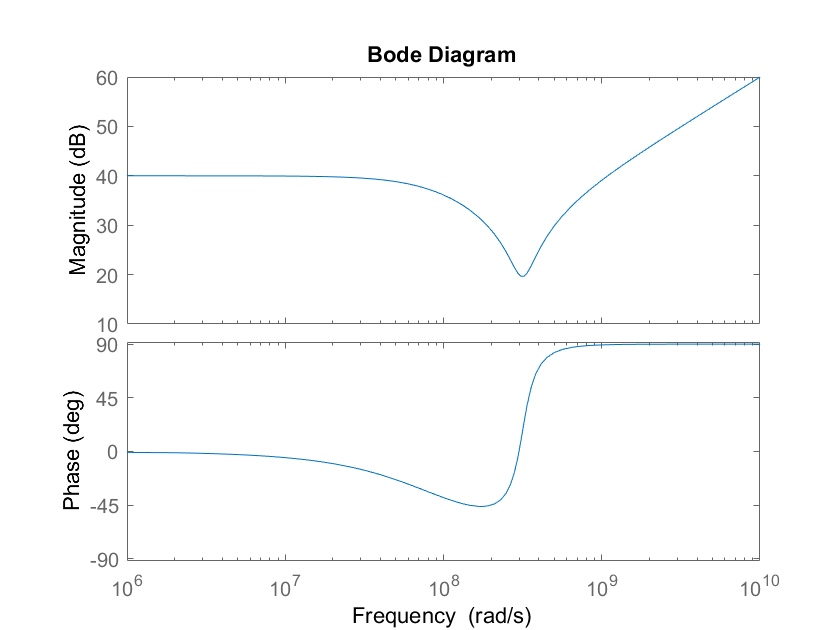


bd =

	resppack.bodeplot



bd=bodeplot(HZ);


% d)

w0 = 1/sqrt(L*C);
Qc = R*sqrt(C/L);
wr = w0*sqrt(1 - 1/(Qc^2))

wr =    300.0000e+006



% e)
w = sqrt(w0)

w =     17.7828e+003


phi_min = -atand(Qc* ( w/w0 - w0/w ) )

phi_min =     89.9990e+000


## Aufgabe 5

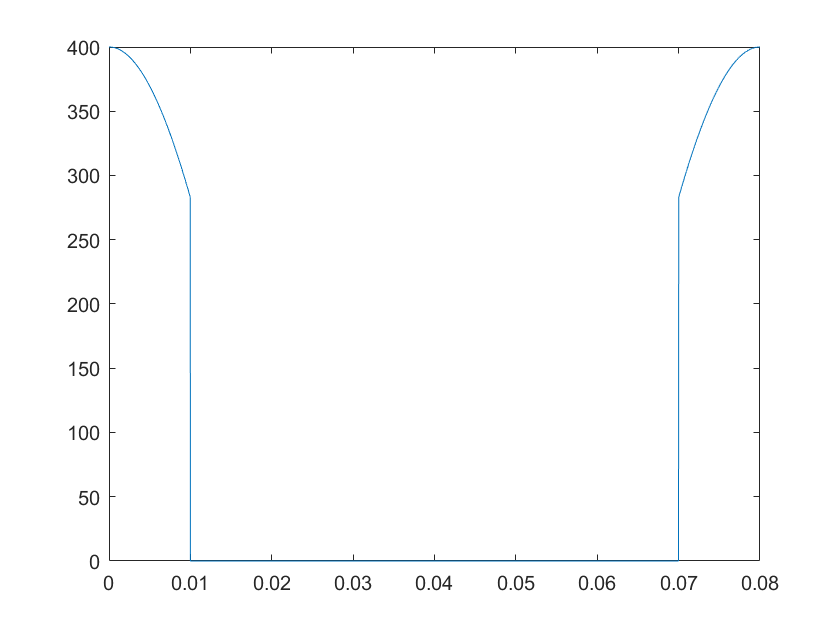

clear
Up = 400;
T = 80e-3;
f = 1/T;
w = 2*pi*f;

t = linspace(0, T, 1e5);
u = Up * cos(w*t);

for k=0:length(u)
    if(k > (length(u)/8) && k < (7*length(u)/8))
        u(k) = 0;
    end
end
% plot(t, u);

Um = mean(u)

Um = 90.0354

Ueff = sqrt(mean(u.^2))

Ueff = 180.9250